# lab 4

## reset

clear, close all

## 1. Завантажте з бібліотеки MATLAB кілька різних зображень.

originalImageCameraman = imread('cameraman.tif');
originalImageMoon = imread('moon.tif');
originalImagePeppers = imread('peppers.png');

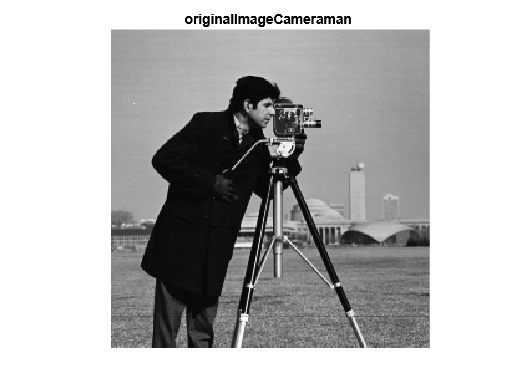

figure, imshow(originalImageCameraman), title('originalImageCameraman ');

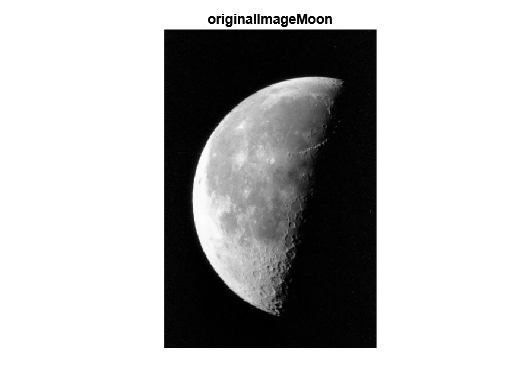

figure, imshow(originalImageMoon), title('originalImageMoon');

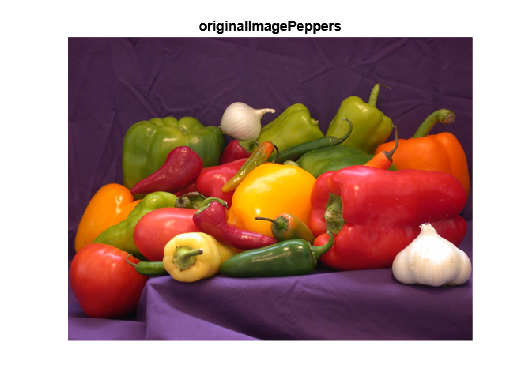

figure, imshow(originalImagePeppers), title('originalImagePeppers');

### *1.1 Підготовка*

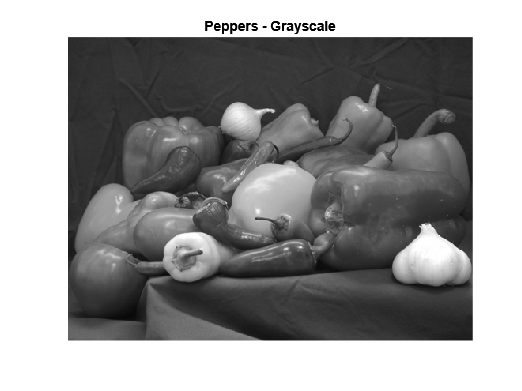

peppersGrayscale = rgb2gray(originalImagePeppers);

figure, imshow(peppersGrayscale), title('Peppers - Grayscale');

## 2. З використанням функції F = fft2(f) сформуйте й відобразіть двовимірні спектри зображень. 

При відображенні спектра використовуйте або логарифмічний масштаб, або підберіть масштаб уручну шляхом ділення значень спектра на деяку константу. Можна, також, пронормувати значення спектра до максимального, а потім домножити кожне значення на 255 (максимальна яскравість для uint8).

### *При відображенні спектра використано логарифмічний масштаб. *

*img->FFT->abs->log->show*

% двовимірне дискретне перетворення Фур’є (FFT – Fast Fourier Transform)
fourierTransformCameraman = fft2( double(originalImageCameraman) );
fourierTransformMoon = fft2(double(originalImageMoon));
fourierTransformPeppers = fft2(double(peppersGrayscale));

% модуль комплексного спектра
spectrumCameraman = abs( fourierTransformCameraman);
spectrumMoon = abs(fourierTransformMoon);
spectrumPeppers = abs(fourierTransformPeppers);

% Логарифмічний маштаб
logSpectrumCameraman = log(1+spectrumCameraman);
logSpectrumMoon = log(1+spectrumMoon);
logSpectrumPeppers = log(1+spectrumPeppers);

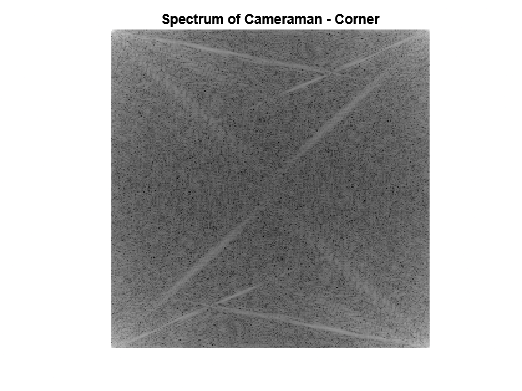

% ілюстрація

figure, 
imshow(logSpectrumCameraman , []), 
title('Spectrum of Cameraman - Corner');

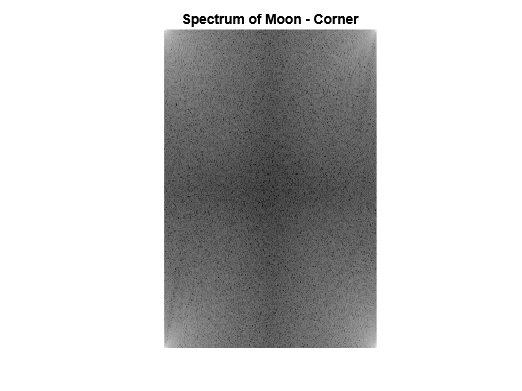


figure, 
imshow( logSpectrumMoon, []), 
title('Spectrum of Moon - Corner');

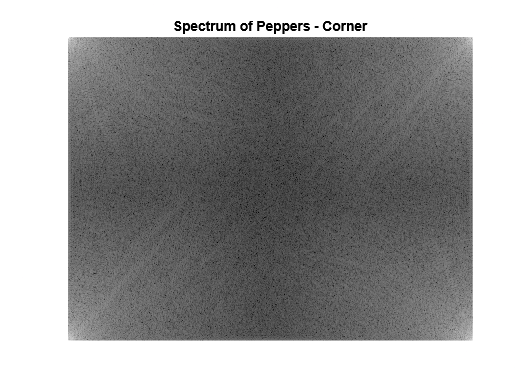


figure,
imshow(logSpectrumPeppers , []),
title('Spectrum of Peppers - Corner');

## 3. З використанням функції fftshift приведіть нульову частоту в спектрі до центру вікна відображення.

*img->FFT-> ****fftshift****-> abs->log->show*

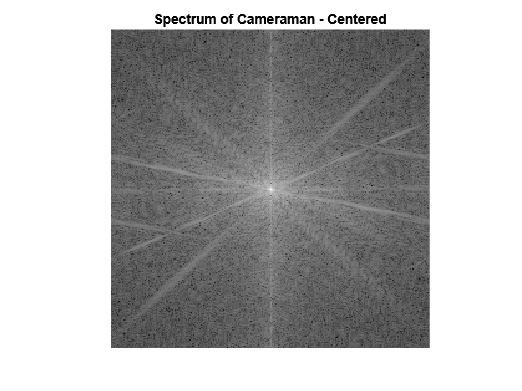

centeredFourierCameraman = fftshift(fourierTransformCameraman);
centeredSpectrumCameraman = abs(centeredFourierCameraman);
logCenteredSpectrumCameraman = log(1+centeredSpectrumCameraman);
figure, imshow(logCenteredSpectrumCameraman, []), title('Spectrum of Cameraman - Centered');

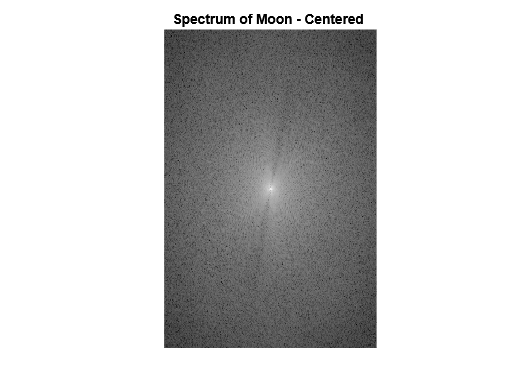

centeredFourierMoon = fftshift(fourierTransformMoon);
centeredSpectrumMoon = abs(centeredFourierMoon);
logCenteredSpectrumMoon = log(1+centeredSpectrumMoon);
figure, imshow(logCenteredSpectrumMoon, []), title('Spectrum of Moon - Centered ');

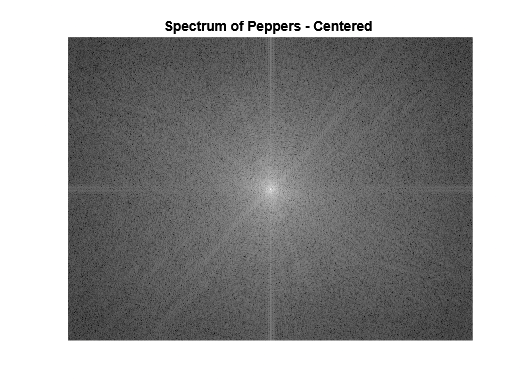

centeredFourierPeppers = fftshift(fourierTransformPeppers);
centeredSpectrumPeppers = abs(centeredFourierPeppers);
logCenteredSpectrumPeppers =  log(1+centeredSpectrumPeppers);
figure, imshow(logCenteredSpectrumPeppers , []), title('Spectrum of Peppers - Centered ');

## 4. відновіть зображення 

З використанням функції ifft 2(F) відновіть зображення за його спектром 

*Виконано відновлення зображень із частотної області (після перетворення Фур'є) назад у просторову область. *

*Це демонструє властивість перетворення Фур'є - його оборотність.*

### 4.1 використовуйте спектри з нульовою частотою у верхньому лівому куті 

(img->FFT)->ifft2->real->show

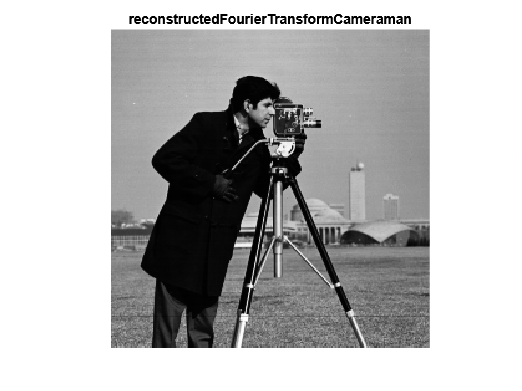

reconstructedFourierTransformCameraman = real(ifft2(fourierTransformCameraman));
figure, imshow(reconstructedFourierTransformCameraman, []), title('reconstructedFourierTransformCameraman');

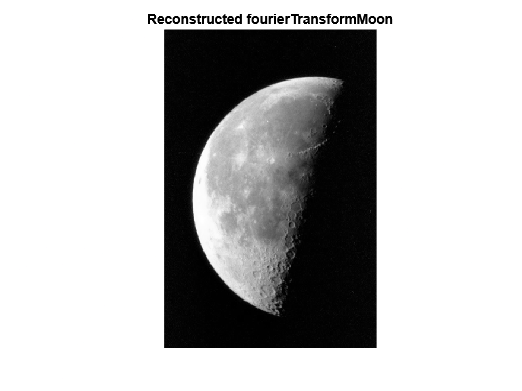

reconstructedFourierTransformMoon = real(ifft2(fourierTransformMoon));
figure, imshow(reconstructedFourierTransformMoon, []), title('Reconstructed fourierTransformMoon');

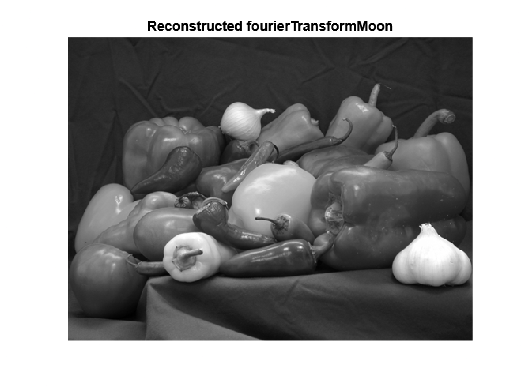

reconstructedFourierTransformPeppers = real(ifft2(fourierTransformPeppers));
figure, imshow(reconstructedFourierTransformPeppers, []), title('Reconstructed fourierTransformMoon');

пертворюю спектр назад у просторову область. Початкове зображення -> перетворення Фур'є (`fft2`) -> отримання спектра. Спектр -> зворотне перетворення Фур'є (`ifft2`) -> відновлене зображення

У нетрансформованому (нецентрованому) спектрі нульова частота знаходиться у верхньому лівому куті матриці. Це стандартне розташування при прямому застосуванні `fft2`, де елемент (0,0) містить інформацію про постійну складову зображення (середню яскравість).

Відновлене зображення виходить ідентичним оригіналу (за винятком невеликих похибок обчислень, що виникають через округлення при обчисленнях з плаваючою точкою).

### 4.2 й з нульовою частотою в центрі вікна

(*img->FFT)-> ****fftshift) -> ifftshift*** ->ifft2->real->show

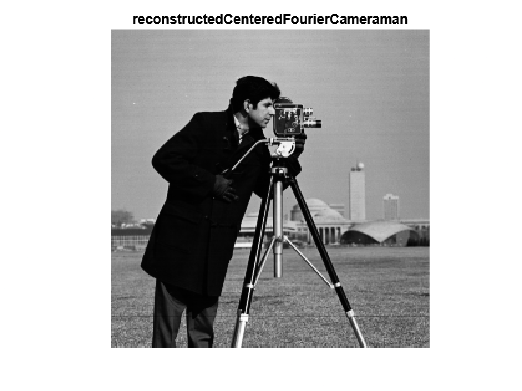

reconstructedCenteredFourierCameraman = real(ifft2(ifftshift(centeredFourierCameraman)));
figure, imshow(reconstructedCenteredFourierCameraman, []), title('reconstructedCenteredFourierCameraman');

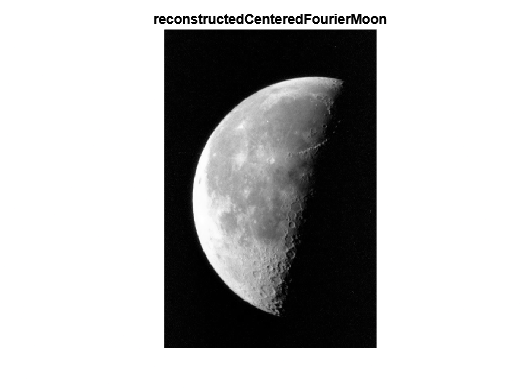

reconstructedCenteredFourierMoon = real(ifft2(ifftshift(centeredFourierMoon)));
figure, imshow(reconstructedCenteredFourierMoon, []), title('reconstructedCenteredFourierMoon');

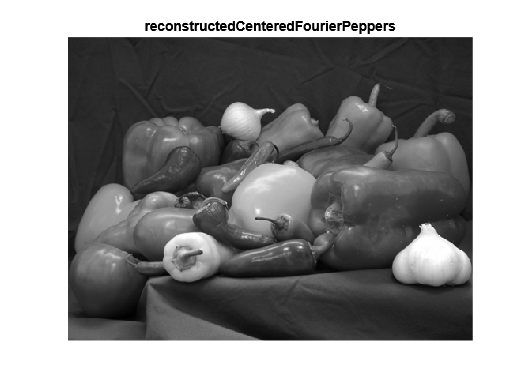

reconstructedCenteredFourierPeppers = real(ifft2(ifftshift(centeredFourierPeppers)));
figure, imshow(reconstructedCenteredFourierPeppers, []), title('reconstructedCenteredFourierPeppers');

Початкове зображення → `fft2` → спектр з нульовою частотою в куті. Спектр → `fftshift` → центрований спектр (нульова частота в центрі). Центрований спектр → `ifftshift` → повернення нульової частоти в кут. Спектр з нульовою частотою в куті → `ifft2` → відновлене зображення

Функція `ifftshift` потрібна тому, що `ifft2` очікує, що нульова частота знаходиться у верхньому лівому куті, а не в центрі. Якщо відновити зображення безпосередньо з центрованого спектра без використання `ifftshift`, буде спотворене зображення:

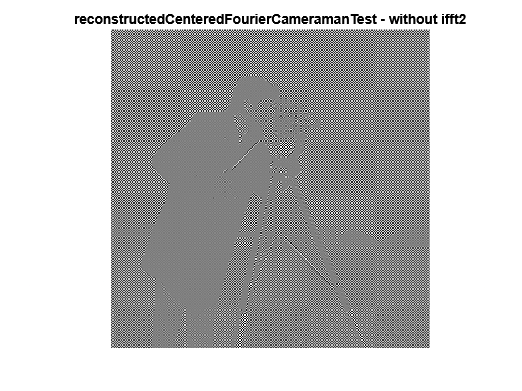

reconstructedCenteredFourierCameramanTest = real(ifft2(centeredFourierCameraman));
figure, imshow(reconstructedCenteredFourierCameramanTest, []), title('reconstructedCenteredFourierCameramanTest - without ifft2');

## 5. (+ пункт 7) З використанням функції fspecial('gaussian') задайте двовимірний фільтр із параметрами [M N], sigma в області просторових змінних. Відобразіть у вигляді зображення вигляд вікна цього фільтра.

% Створення вікон гаусових фільтрів
[imageHeight, imageWidth] = size(originalImageCameraman);

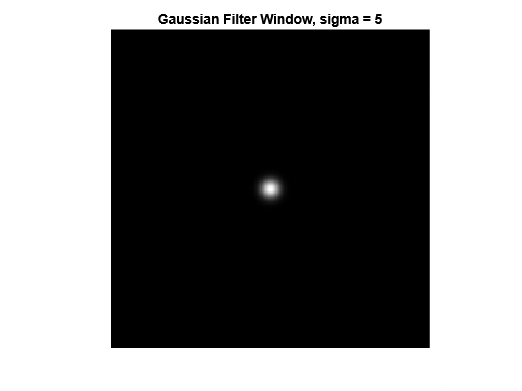

% Перший фільтр з малою сигмою (вузьке вікно)
sigmaSmall = 5;  
gaussianFilterSmall = fspecial('gaussian', [imageHeight imageWidth], sigmaSmall);
figure, imshow(gaussianFilterSmall, []), title(['Gaussian Filter Window, sigma = ', num2str(sigmaSmall)]);

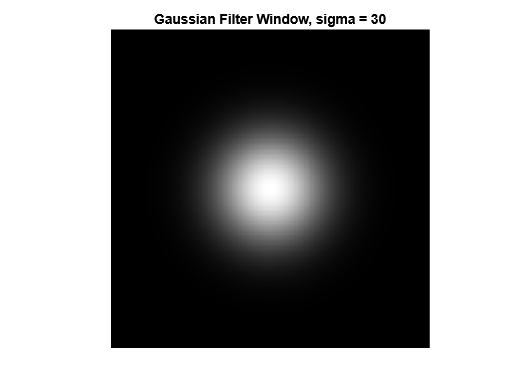

% Другий фільтр з великою сигмою (широке вікно)
sigmaLarge = 30;  
gaussianFilterLarge = fspecial('gaussian', [imageHeight imageWidth], sigmaLarge);
figure, imshow(gaussianFilterLarge, []), title(['Gaussian Filter Window, sigma = ', num2str(sigmaLarge)]);

## 6. (+ пункт 7) Визначте вигляд частотної характеристики даного фільтра. Відобразіть АЧХ двовимірного фільтра у вигляді зображення – imshow.

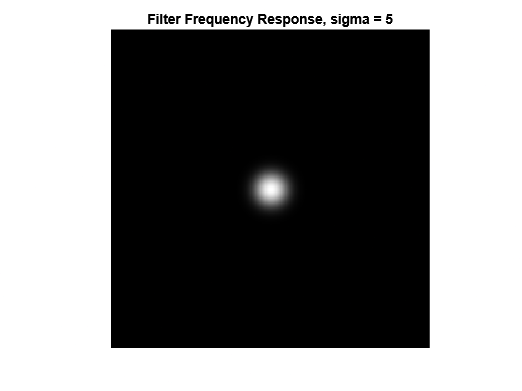

filterFrequencyResponseSmall = fft2(gaussianFilterSmall);
centeredFilterResponseSmall = fftshift(filterFrequencyResponseSmall);
figure, imshow(log(1+abs(centeredFilterResponseSmall)), []), title(['Filter Frequency Response, sigma = ', num2str(sigmaSmall)]);

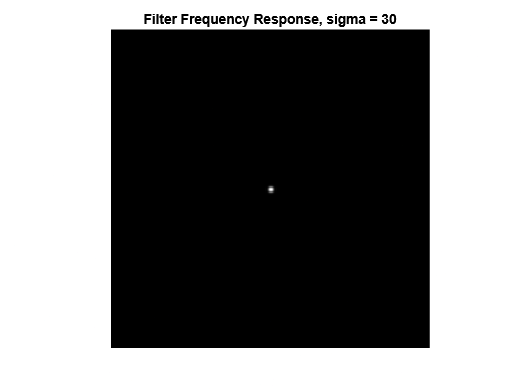

filterFrequencyResponseLarge = fft2(gaussianFilterLarge);
centeredFilterResponseLarge = fftshift(filterFrequencyResponseLarge);
figure, imshow(log(1+abs(centeredFilterResponseLarge)), []), title(['Filter Frequency Response, sigma = ', num2str(sigmaLarge)]);

## 7. Змініть параметр sigma фільтра, і повторіть п.п. 5,6. Поясніть відмінності в отриманих результатах.

*Фільтр з малим sigma зберігає більше деталей зображення, виконуючи лише легке згладжування.*

*Фільтр з великим sigma значно розмиває зображення, видаляючи дрібні деталі та шуми, але зберігаючи лише загальну структуру зображення.*

***В просторовій області:***

*Малий: створює вузьке вікно фільтра з різким піком у центрі. Це означає, що фільтр впливає лише на близькі пікселі*

*Великий: створює широке, розмите вікно з пологим переходом від центра до країв. Такий фільтр охоплює більшу область зображення*

***В частотній області:***

*Малий: створює широкий спектр, що пропускає низькі і більшість середніх частот. фільтр пропускає великі та дрібні деталі зображення.*

*Великий: створює дуже вузький спектр, зосереджений навколо нульової частоти. сильно подавлює високі частоти (дрібні деталі), пропускаючи переважно низькі частоти (великі елементи зображення).*

## 8. Виконайте фільтрацію зображень у частотній області з використанням фільтрів згідно п.п. 5, 6, 7. Поясніть відмінності в отриманих результатах.

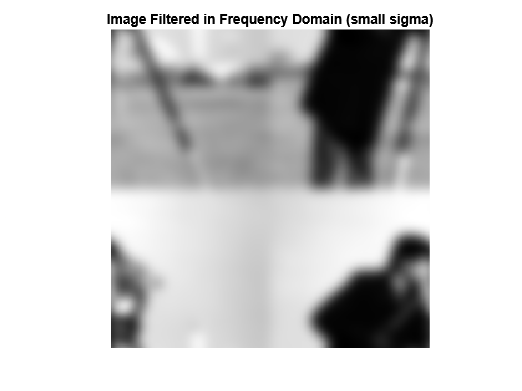

filteredFourierSmallSigma = fourierTransformCameraman .* filterFrequencyResponseSmall;
filteredImageSmallSigma = real(ifft2(filteredFourierSmallSigma));
figure, imshow(filteredImageSmallSigma, []), title('Image Filtered in Frequency Domain (small sigma)');

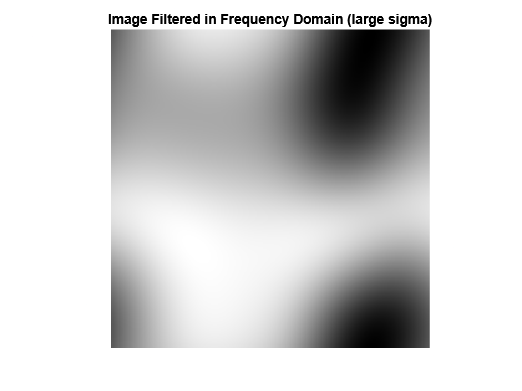

filteredFourierLargeSigma = fourierTransformCameraman .* filterFrequencyResponseLarge;
filteredImageLargeSigma = real(ifft2(filteredFourierLargeSigma));
figure, imshow(filteredImageLargeSigma, []), title('Image Filtered in Frequency Domain (large sigma)');

*Фільтр з великою sigma у просторовій області має дуже вузьку смугу пропускання в частотній області, тому він пропускає переважно низькочастотні компоненти, видаляючи більшість середніх і всі високі частоти. (Більше sigma - сильніше розмиття)*

## 9. З використанням того самого віконного фільтра, заданого функцією fspecial('gaussian'),  виконайте фільтрацію зображення в області просторових змінних. 

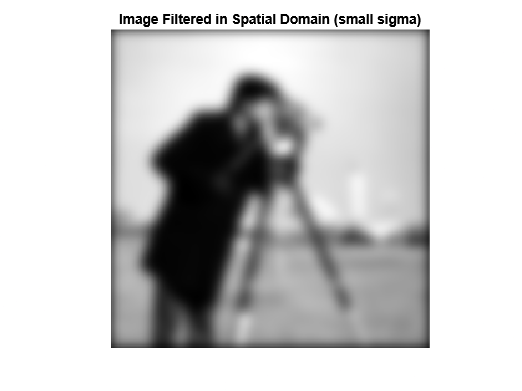

spatialFilteredSmallSigma = imfilter(double(originalImageCameraman), gaussianFilterSmall, 'same');
figure, imshow(spatialFilteredSmallSigma, []), title('Image Filtered in Spatial Domain (small sigma)');

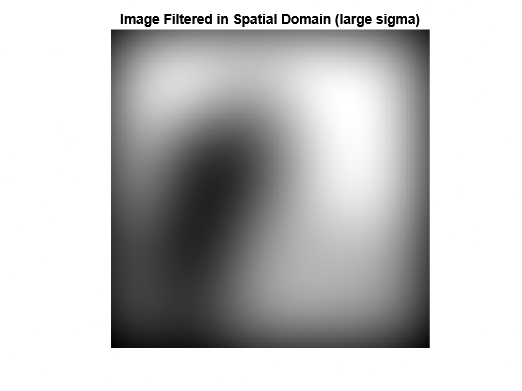

spatialFilteredLargeSigma = imfilter(double(originalImageCameraman), gaussianFilterLarge, 'same');
figure, imshow(spatialFilteredLargeSigma, []), title('Image Filtered in Spatial Domain (large sigma)');

*Фільтр з великою sigma у просторовій області має дуже вузьку смугу пропускання в частотній області, тому він пропускає переважно низькочастотні компоненти, видаляючи більшість середніх і всі високі частоти. (Більше sigma - сильніше розмиття)*

## 9,1 Порівняйте результат з п.8.

*фільтрація в просторовій області (пункт 9) *

*зазвичай дає більш передбачувані та точні результати без артефактів зсуву. *

*фільтрація в частотній області (пункт 8) *

*може бути обчислювально ефективнішою для великих фільтрів, *

*оскільки множення в частотній області вимагає менше операцій, ніж згортка в просторовій.*